cd('/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220914AChsensorHEK003')

load('analysis_offset0/*.mat')

Error using load
Unable to find file or directory 'analysis_offset0/*.mat'.

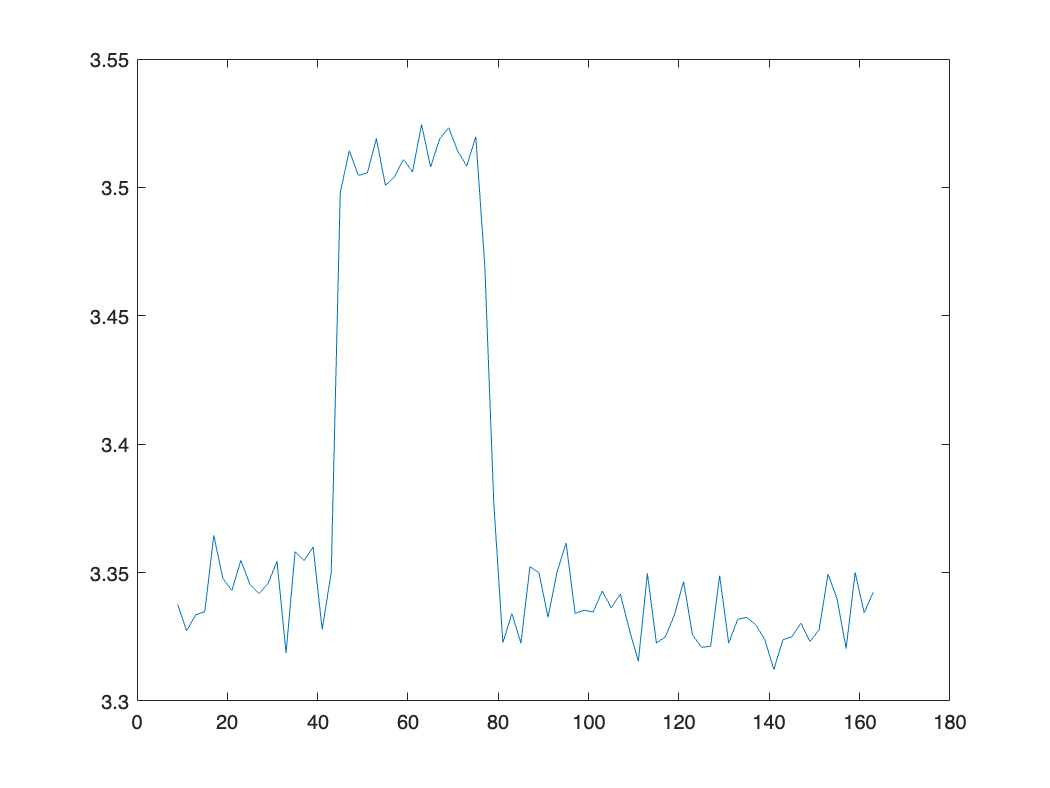

figure
plot(stateYao.CyclePositions(:,2),lft2(:,1))

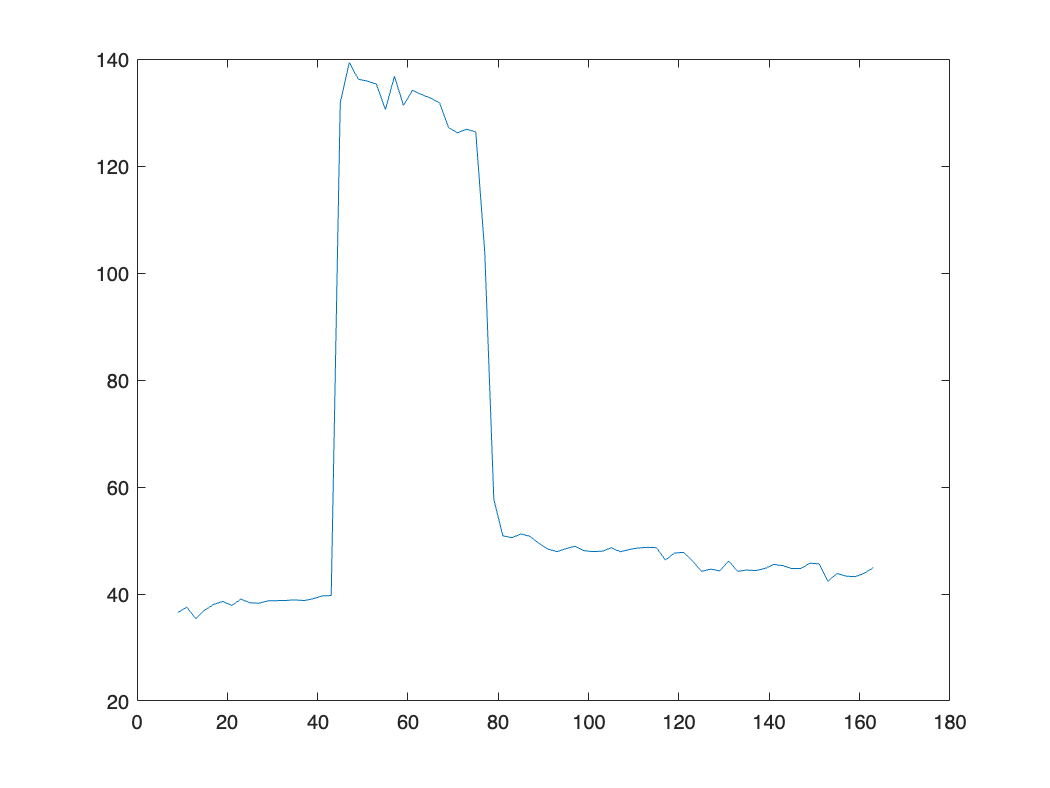


figure
plot(stateYao.CyclePositions(:,2),intensity2(:,1))

% baseline, ACh, Tio, ACh+Tio
acqs = [27, 59, 91, 161]

acqs =     27    59    91   161


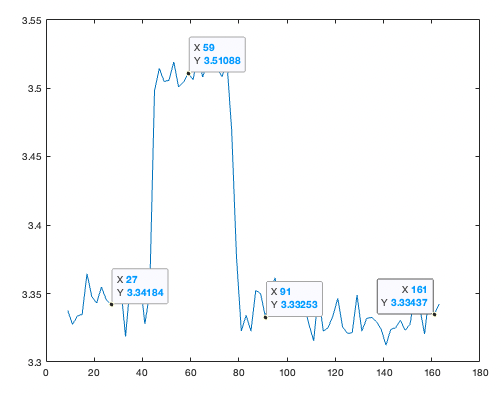

edit Fix_offset.m

global offset fixedoffset
fixedoffset=1;
% offset=spc.switchess{1}.figOffset;
offset=0;

spc_openCurves('/Volumes/yaochen/Active/Pingchuan/2022Fall/20220914AChsensorHEK003/20220914AChsensorHEK003FLIM027.mat')

Reading /Volumes/yaochen/Active/Pingchuan/2022Fall/20220914AChsensorHEK003/20220914AChsensorHEK003FLIM027.mat


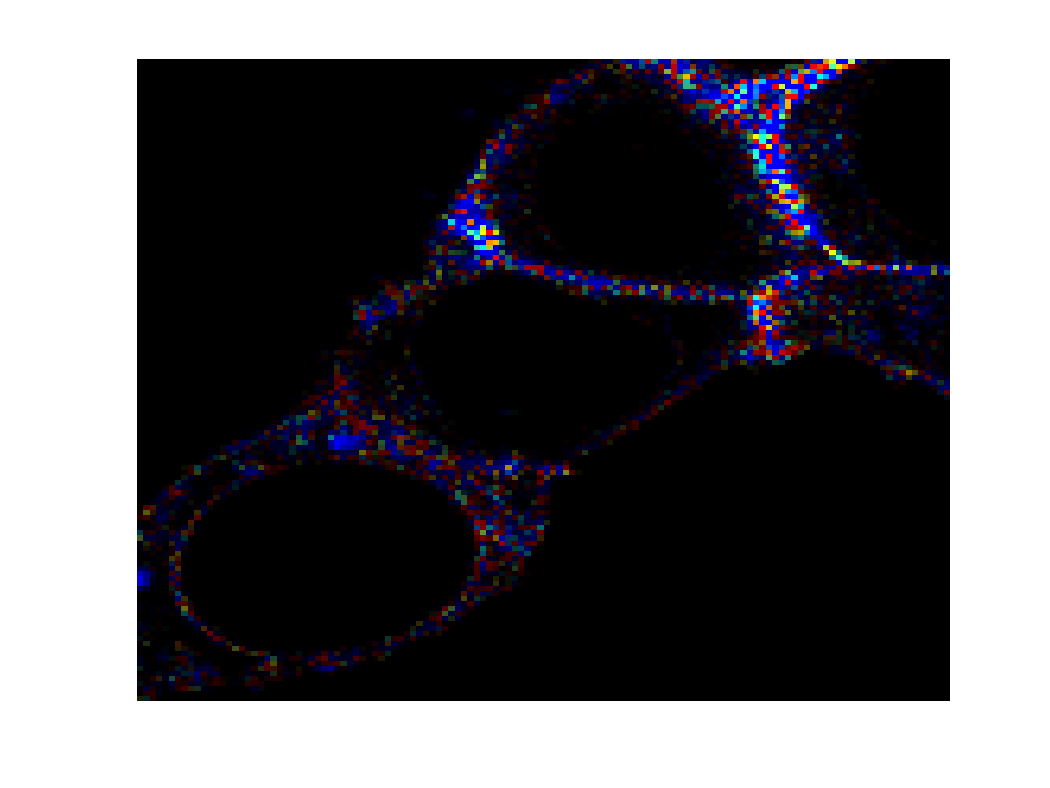

chan=1;

figure
image(spc.rgbLifetimes{chan});
axis off;


figure
h=heatmap(spc.projects{1});
h.Colormap=gray

h =   HeatmapChart with properties:

        XData: {128×1 cell}
        YData: {128×1 cell}
    ColorData: [128×128 double]

  Show all properties


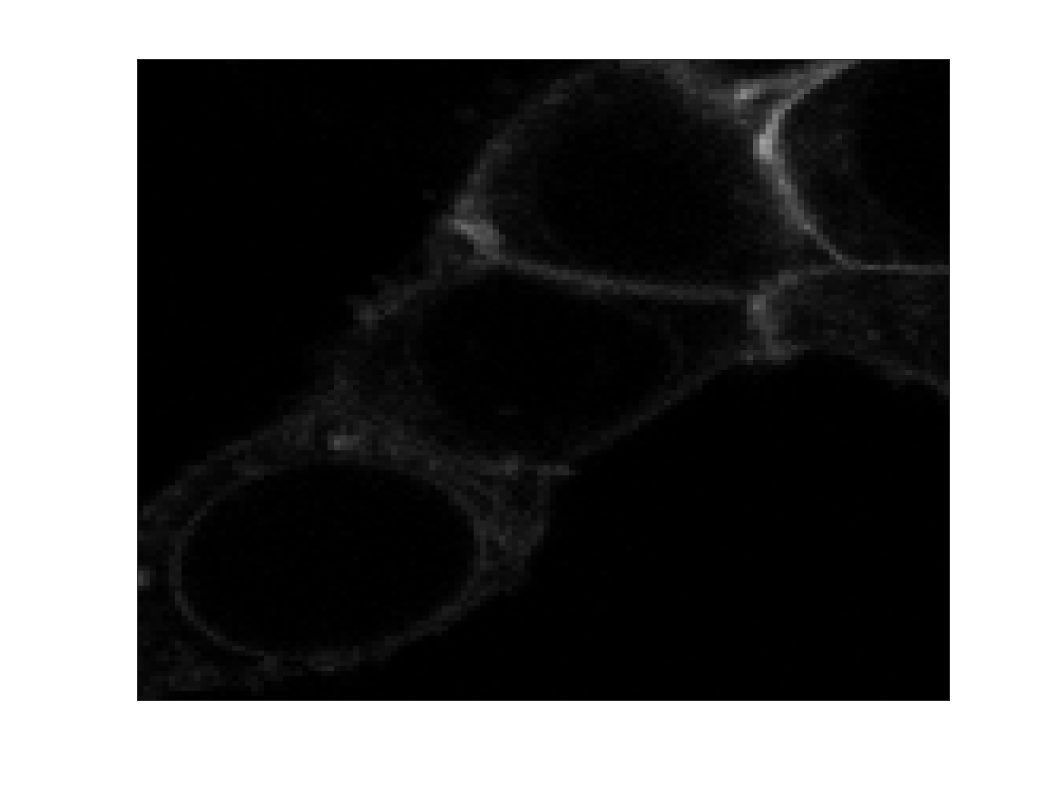

Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 400];

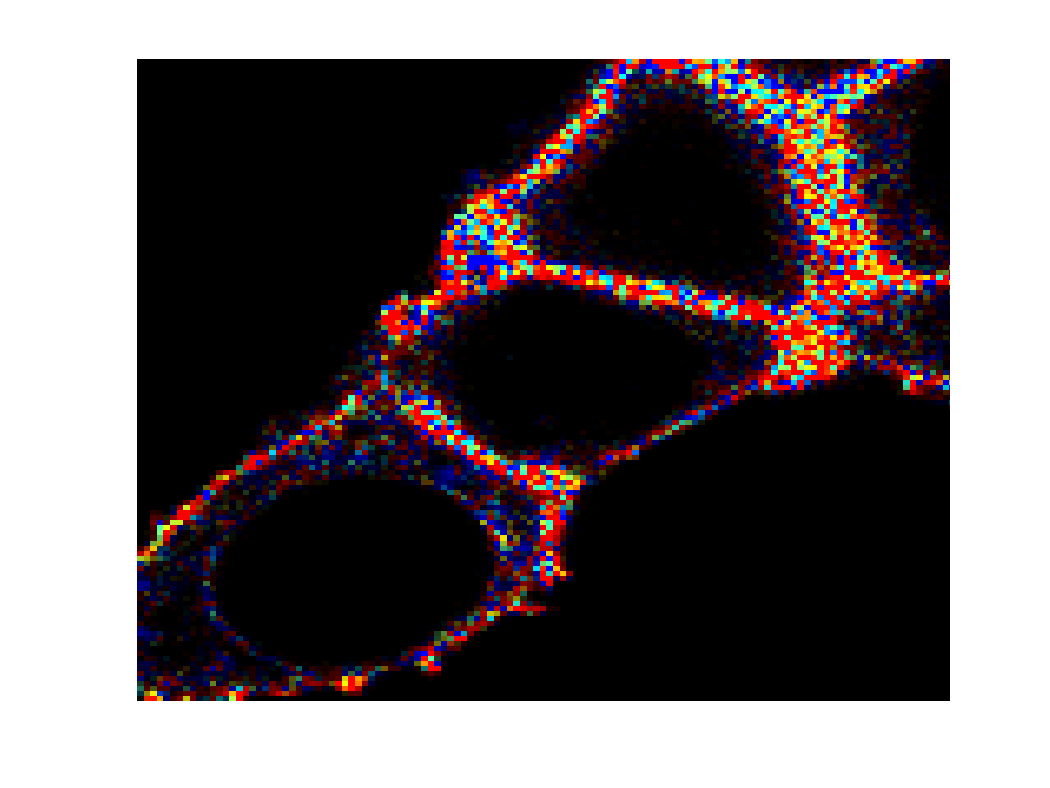

chan=1;

figure
image(spc.rgbLifetimes{chan});
axis off;


figure
h=heatmap(spc.projects{1});
h.Colormap=gray

h =   HeatmapChart with properties:

        XData: {128×1 cell}
        YData: {128×1 cell}
    ColorData: [128×128 double]

  Show all properties


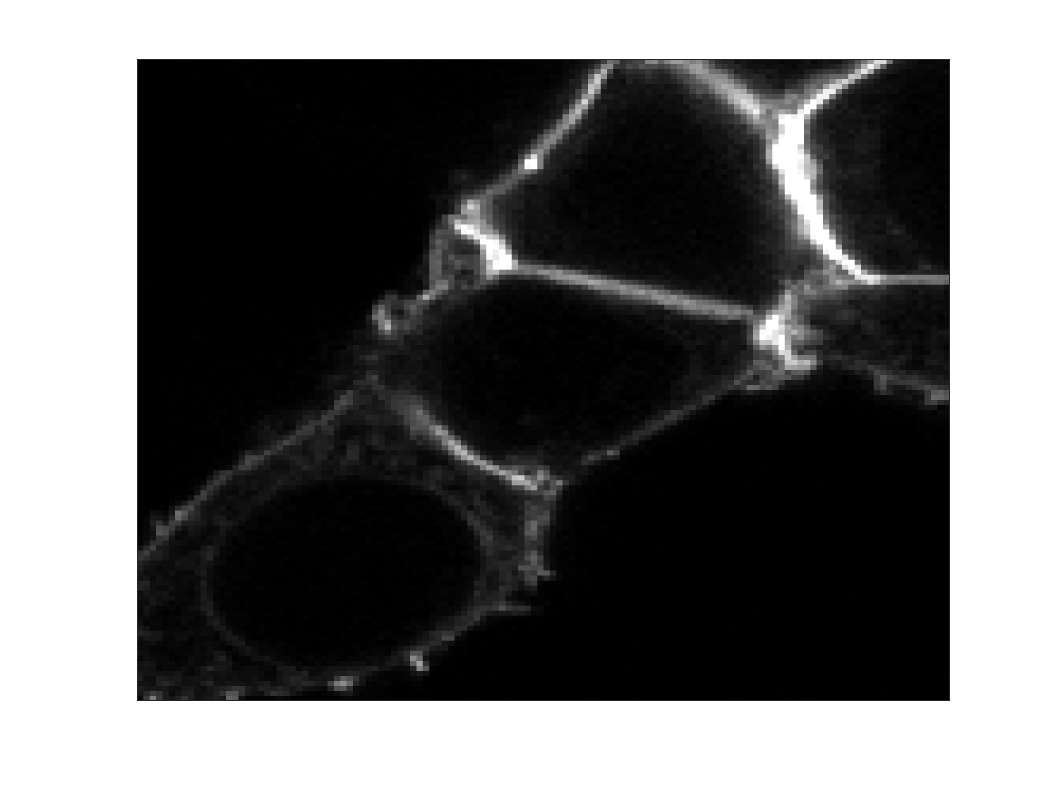

Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 400];

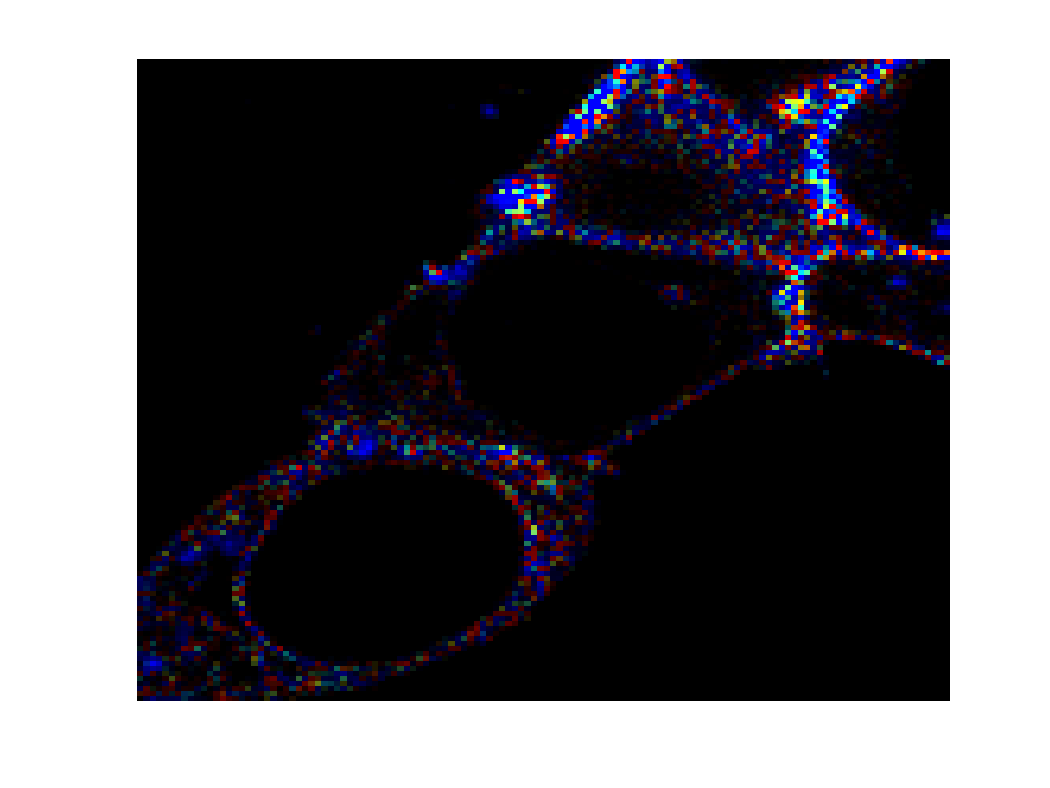

chan=1;

figure
image(spc.rgbLifetimes{chan});
axis off;


figure
h=heatmap(spc.projects{1});
h.Colormap=gray

h =   HeatmapChart with properties:

        XData: {128×1 cell}
        YData: {128×1 cell}
    ColorData: [128×128 double]

  Show all properties


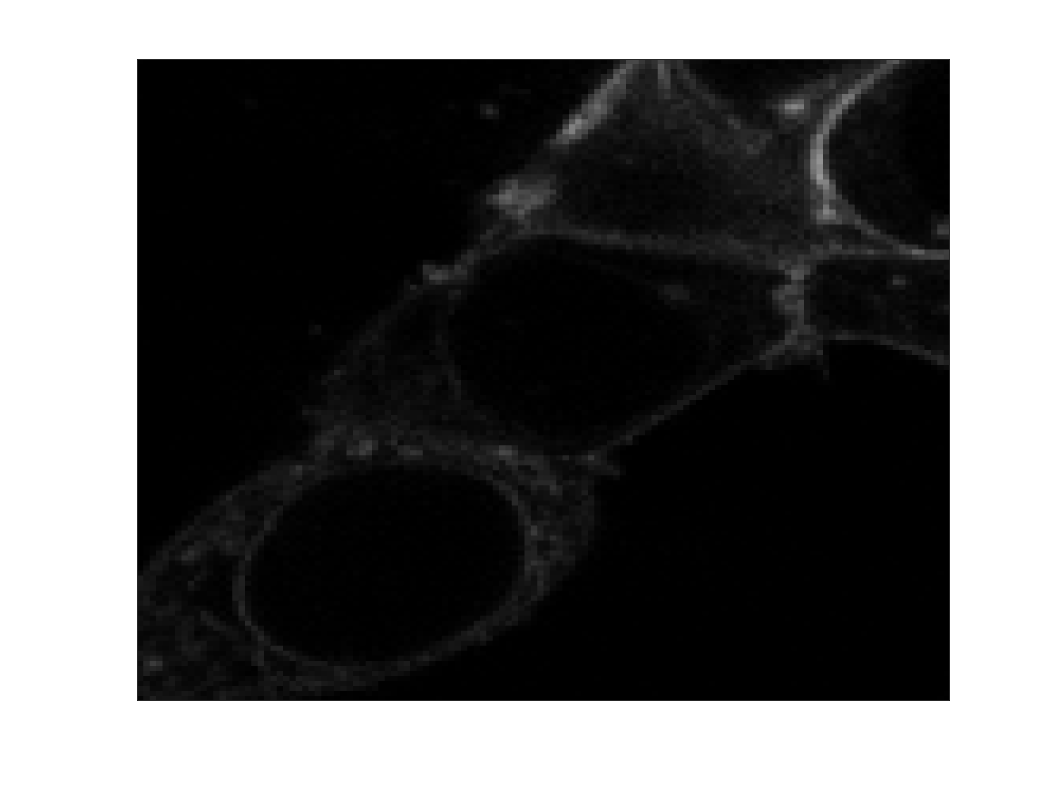

Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 400];chan=1;

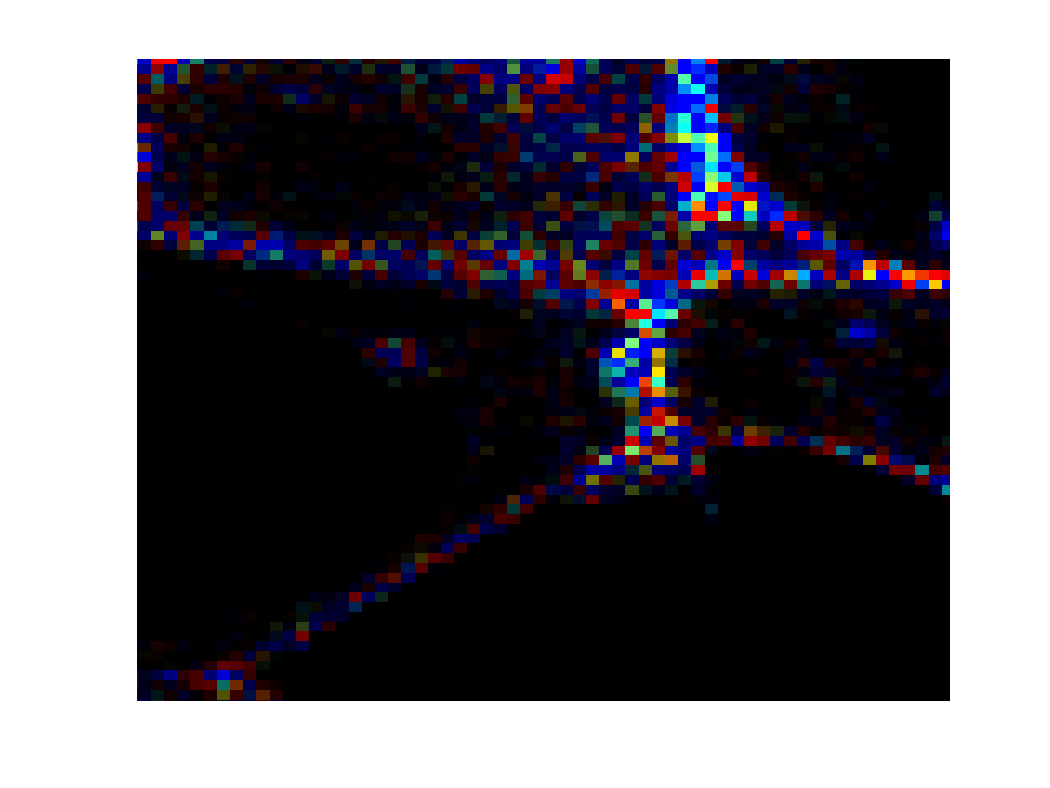


figure
image(spc.rgbLifetimes{chan});
axis off;


figure
h=heatmap(spc.projects{1});
h.Colormap=gray

h =   HeatmapChart with properties:

        XData: {128×1 cell}
        YData: {128×1 cell}
    ColorData: [128×128 double]

  Show all properties


Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 400];

lft1_norm =zeros(size(lft1,1),size(lft1,2));

for i=1:4
    max_lft = max(lft1(:,i));
    min_lft = min(lft1(:,i));
    lft1_norm(:,i) = (lft1(:,i)-min_lft)/(max_lft - min_lft);
end

lft2_norm =zeros(size(lft2,1),size(lft2,2));

for i=1:4
    max_lft = max(lft2(:,i));
    min_lft = min(lft2(:,i));
    lft2_norm(:,i) = (lft2(:,i)-min_lft)/(max_lft - min_lft);
end

AcqTime_all = [];

for i = 1:size(AcqTime,1)
    AcqTime_all((i-1)*2+1) = AcqTime(i,1);
    AcqTime_all((i-1)*2+2) = AcqTime(i,2);
end

lft_norm = NaN(size(AcqTime_all,1), 8);

for i = 1:size(AcqTime,1)
    lft_norm((i-1)*2+1,1:4) = lft1_norm(i,:);
    lft_norm((i-1)*2+2,5:8) = lft2_norm(i,:);
end

intensity1_norm =zeros(size(intensity1,1),size(intensity1,2));

for i=1:4
    max_intensity = max(intensity1(:,i));
    min_intensity = min(intensity1(:,i));
    intensity1_norm(:,i) = (intensity1(:,i)-min_intensity)/(max_intensity - min_intensity);
end

intensity2_norm =zeros(size(intensity2,1),size(intensity2,2));

for i=1:4
    max_intensity = max(intensity2(:,i));
    min_intensity = min(intensity2(:,i));
    intensity2_norm(:,i) = (intensity2(:,i)-min_intensity)/(max_intensity - min_intensity);
end

AcqTime_all = [];

for i = 1:size(AcqTime,1)
    AcqTime_all((i-1)*2+1) = AcqTime(i,1);
    AcqTime_all((i-1)*2+2) = AcqTime(i,2);
end

intensity_norm = NaN(size(AcqTime_all,1), 8);

for i = 1:size(AcqTime,1)
    intensity_norm((i-1)*2+1,1:4) = intensity1_norm(i,:);
    intensity_norm((i-1)*2+2,5:8) = intensity2_norm(i,:);
end



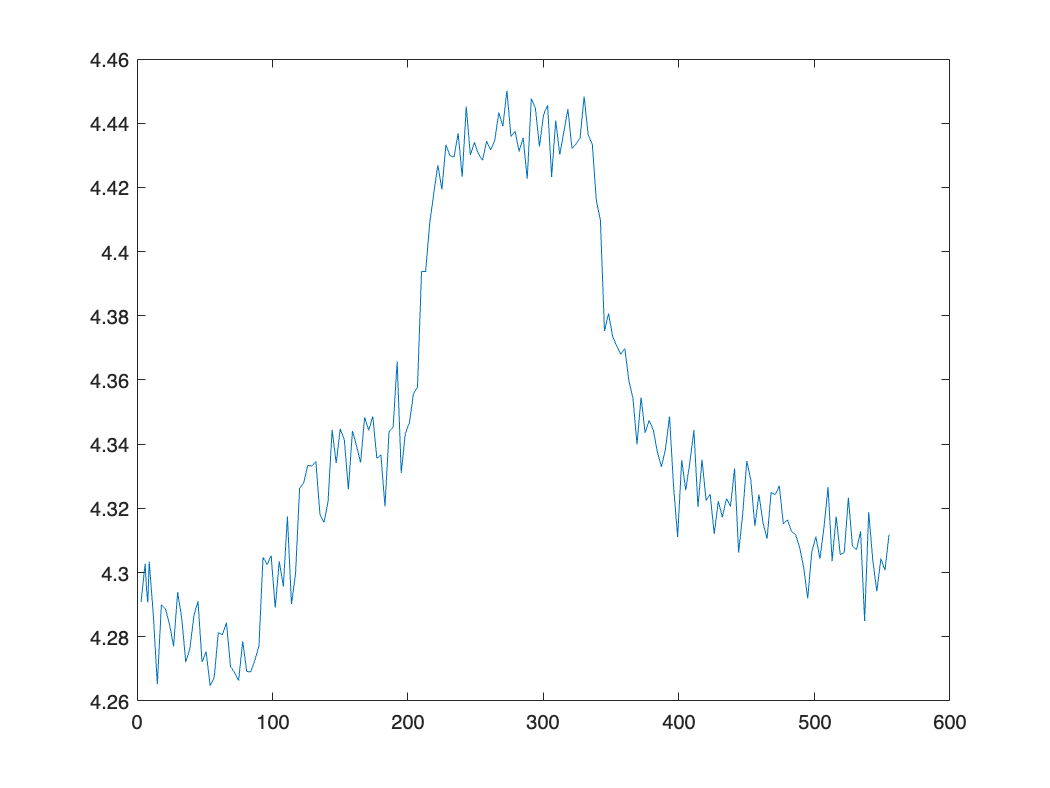

figure
plot(stateYao.CyclePositions(:,1),lft1(:,1))

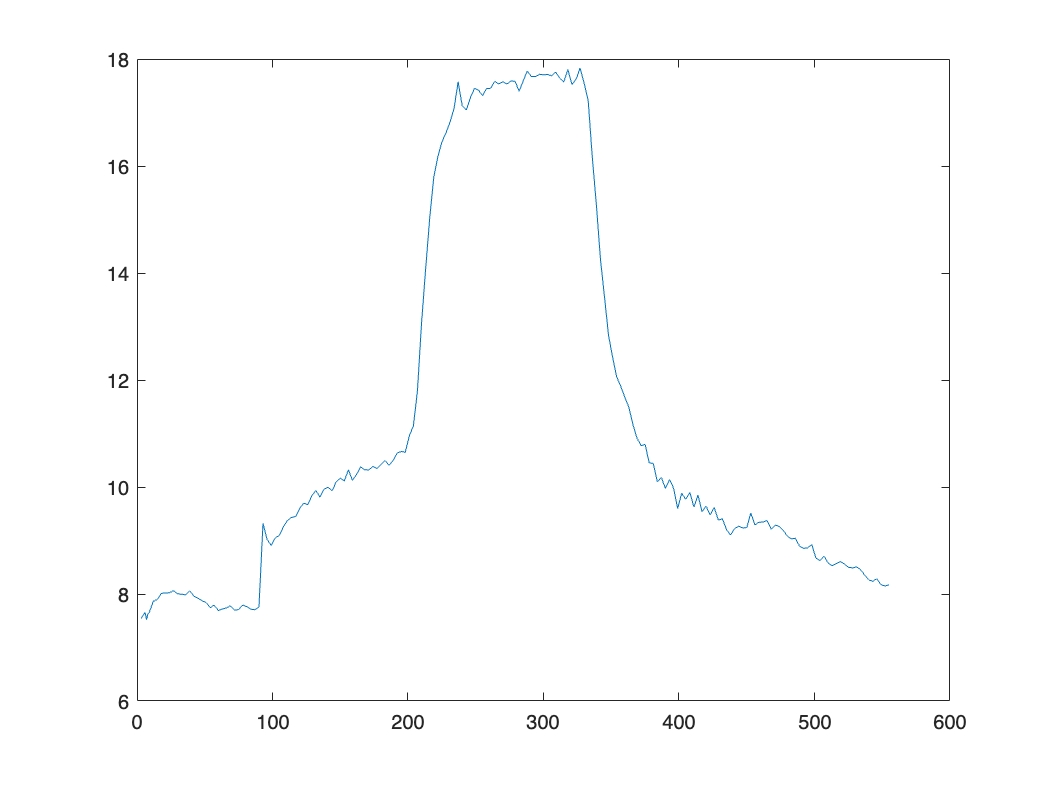


figure
plot(stateYao.CyclePositions(:,1),intensity1(:,1))

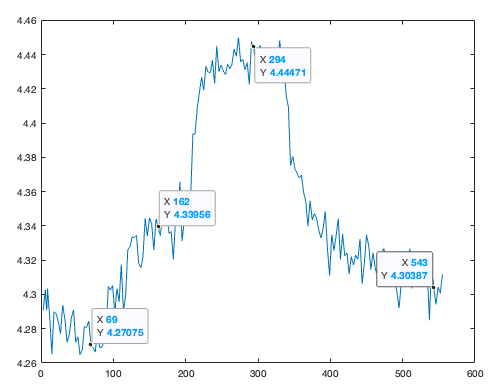

Acqs=[10 162 294 543]

global offset fixedoffset
fixedoffset=1;
% offset=spc.switchess{1}.figOffset;
offset=0;

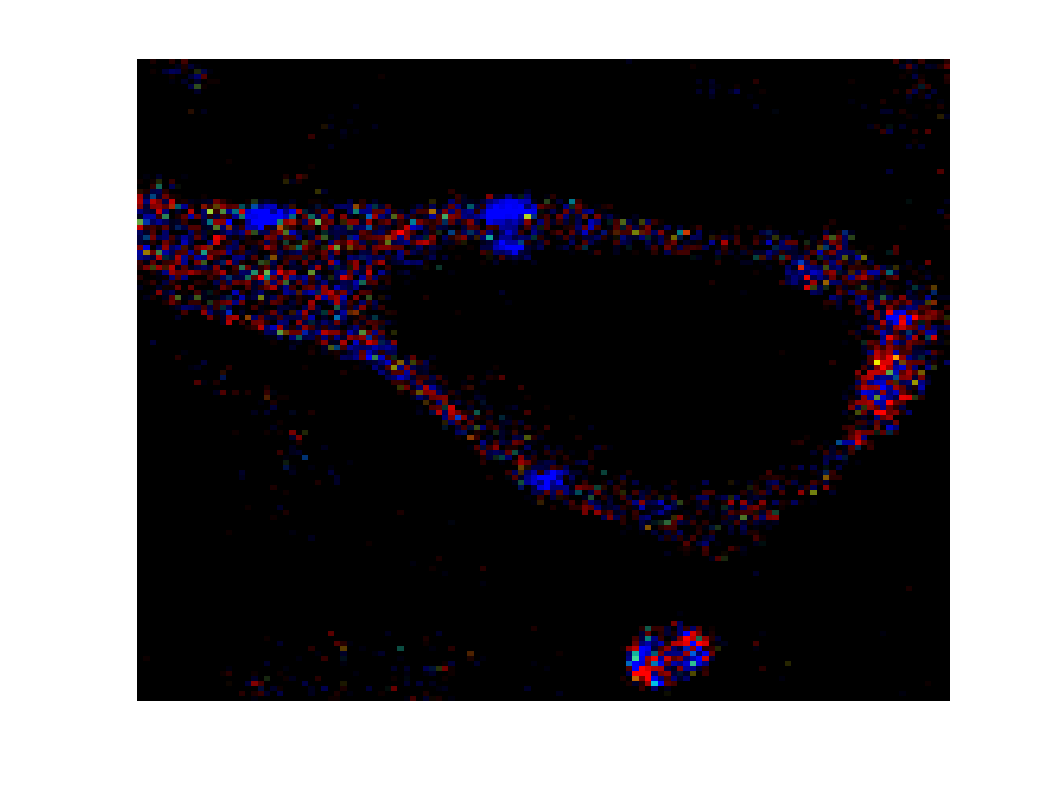

chan=1;

figure
image(spc.rgbLifetimes{chan});
axis off;


figure
h=heatmap(spc.projects{1});
h.Colormap=gray

h =   HeatmapChart with properties:

        XData: {128×1 cell}
        YData: {128×1 cell}
    ColorData: [128×128 double]

  Show all properties


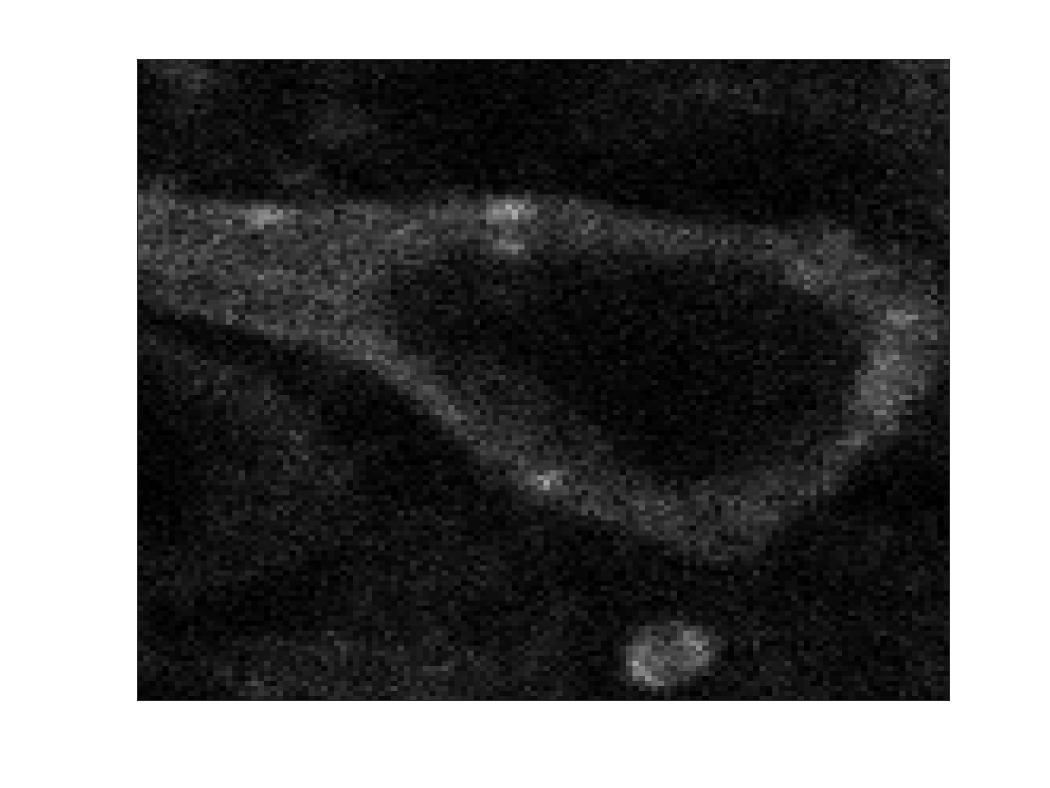

Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 70];

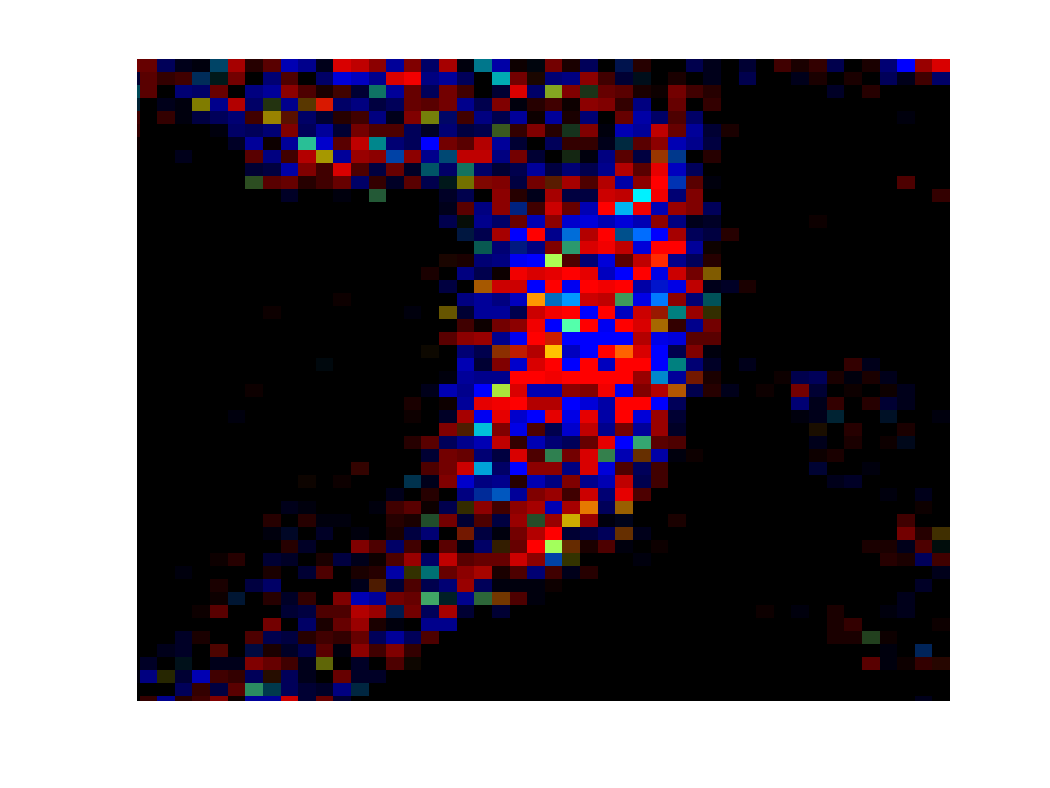

chan=1;

figure
image(spc.rgbLifetimes{chan});
axis off;


figure
h=heatmap(spc.projects{1});
h.Colormap=gray

h =   HeatmapChart with properties:

        XData: {128×1 cell}
        YData: {128×1 cell}
    ColorData: [128×128 double]

  Show all properties


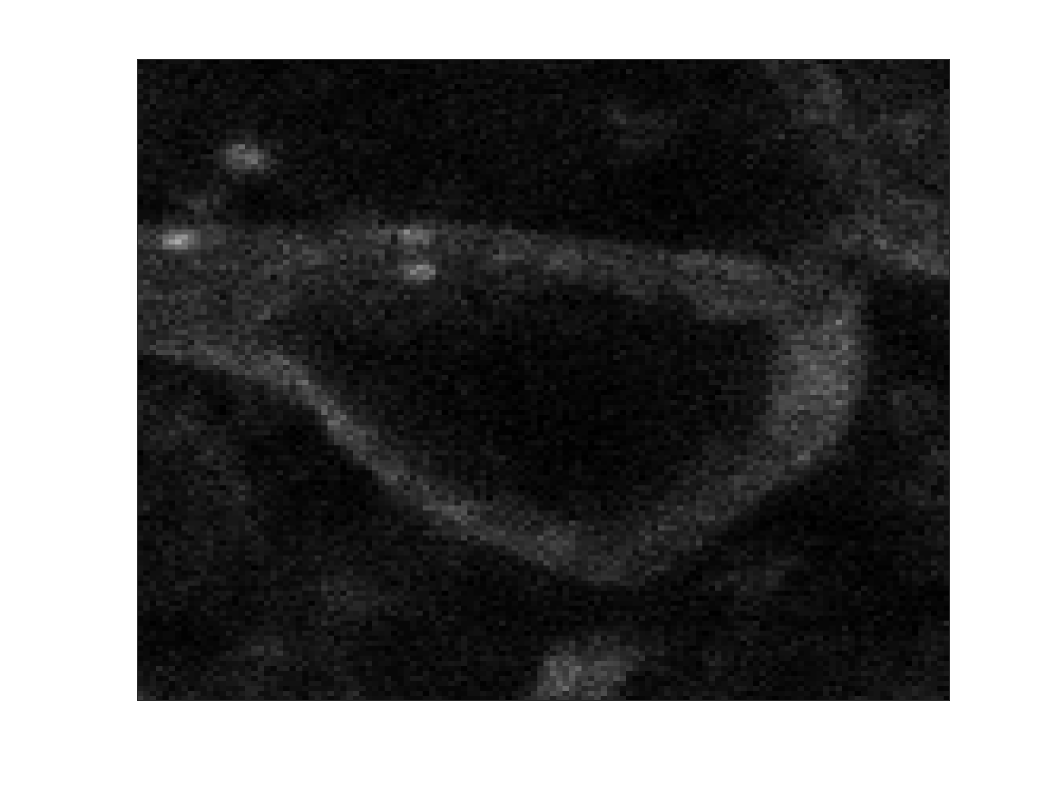

Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 100];

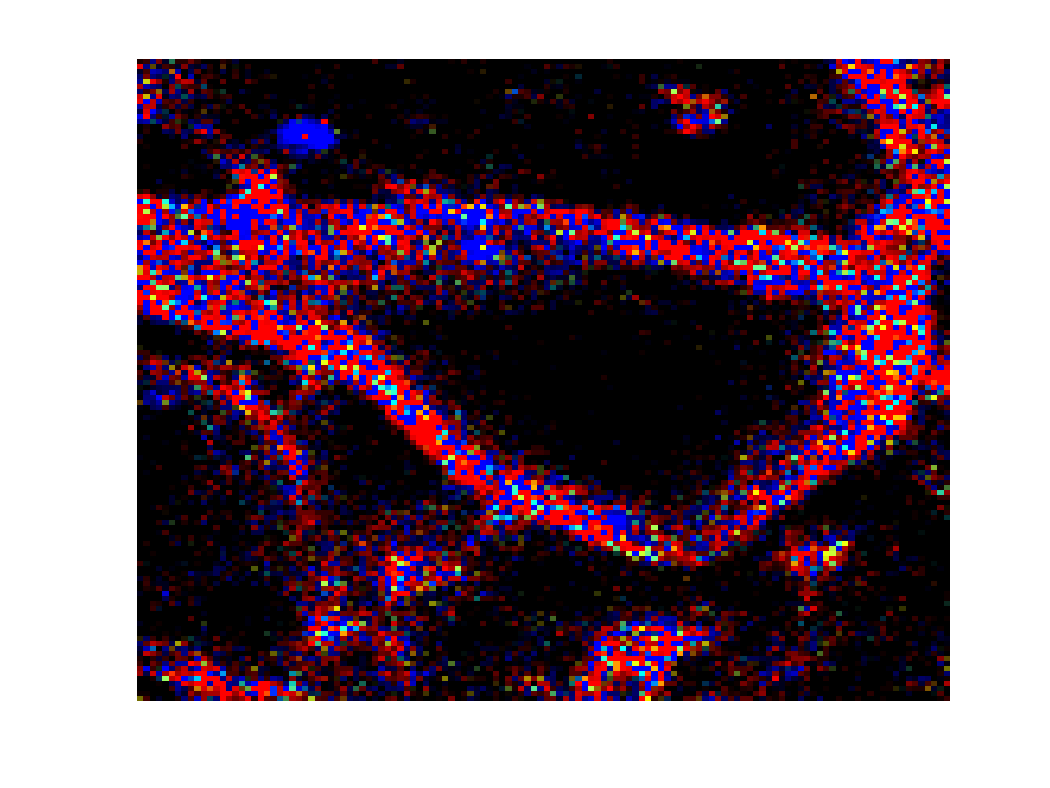

chan=1;

figure
image(spc.rgbLifetimes{chan});
axis off;


figure
h=heatmap(spc.projects{1});
h.Colormap=gray

h =   HeatmapChart with properties:

        XData: {128×1 cell}
        YData: {128×1 cell}
    ColorData: [128×128 double]

  Show all properties


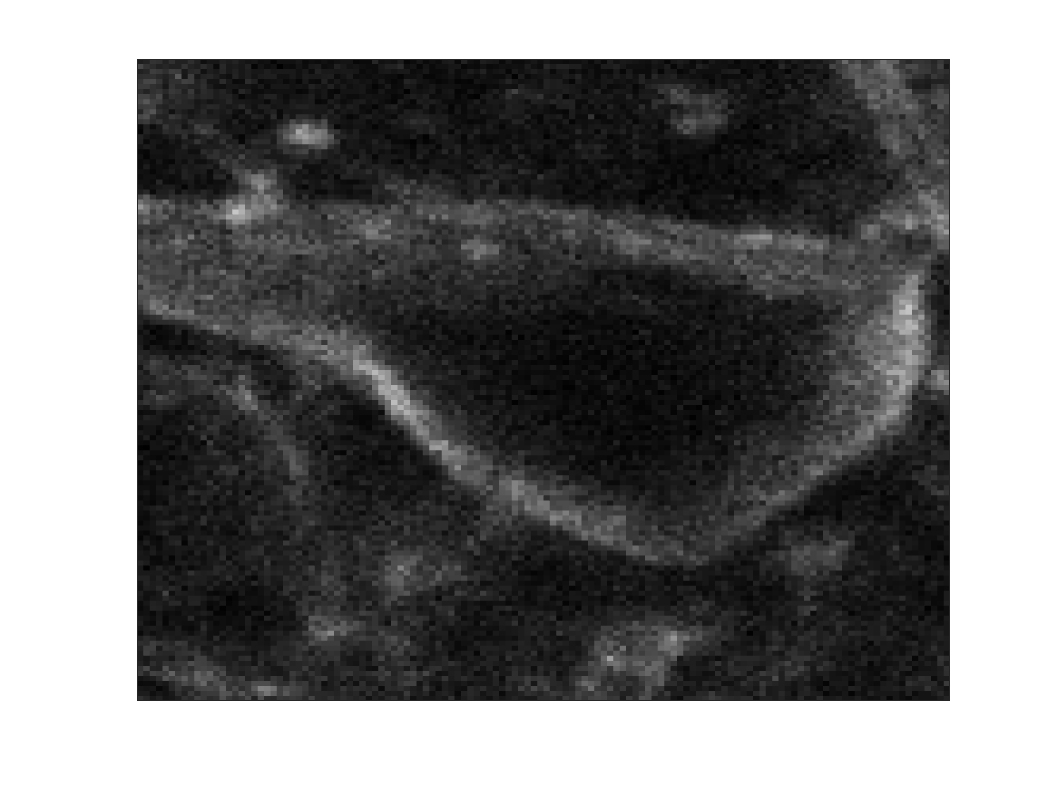

Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 100];

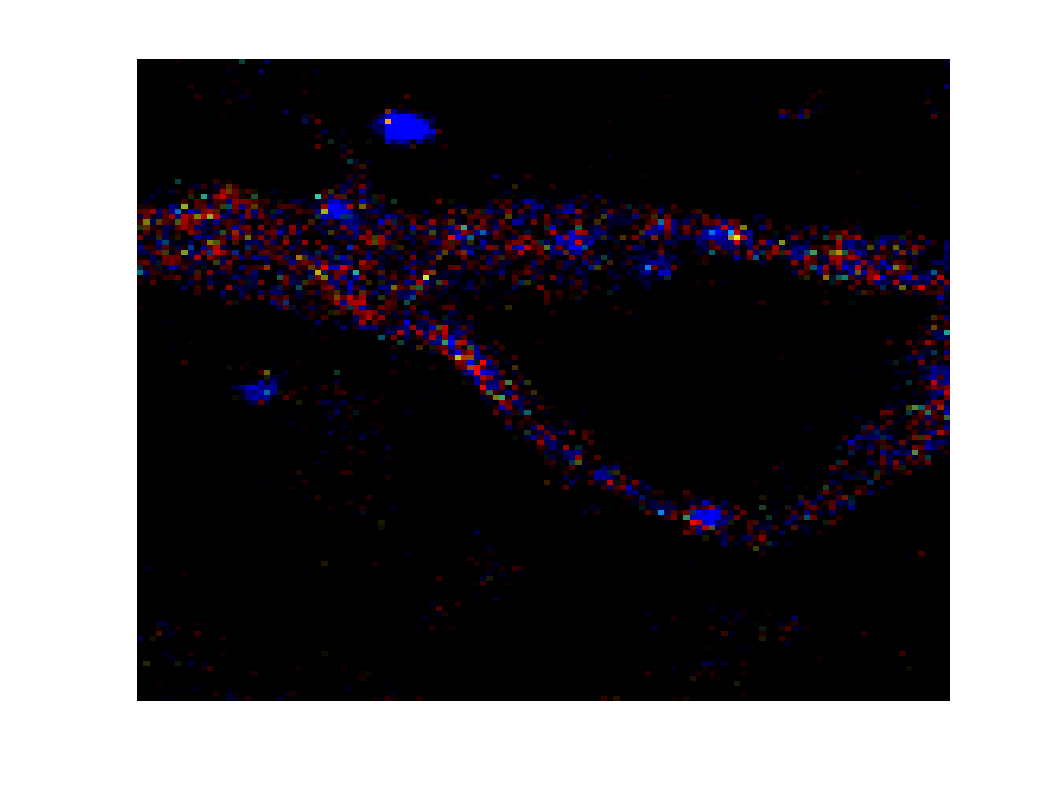

chan=1;

figure
image(spc.rgbLifetimes{chan});
axis off;


figure
h=heatmap(spc.projects{1});
h.Colormap=gray

h =   HeatmapChart with properties:

        XData: {128×1 cell}
        YData: {128×1 cell}
    ColorData: [128×128 double]

  Show all properties


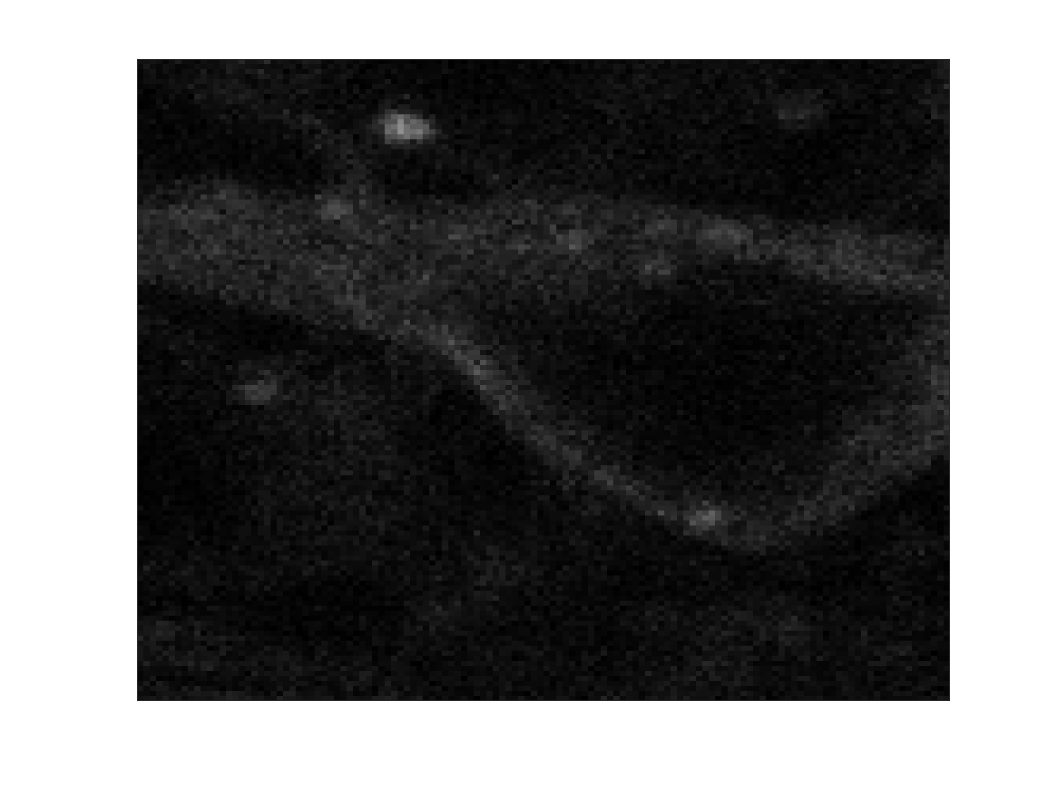

Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 100];

epochchange_time =[];
for i=1:size(EpochStartAcq1,2)
    epochchange_time(i) = AcqTime1(EpochStartAcq1(i))
end

epochchange_time = 0

epochchange_time =          0    5.0833


epochchange_time =          0    5.0833   10.7500


epochchange_time =          0    5.0833   10.7500   16.3000


epochchange_time =          0    5.0833   10.7500   16.3000   20.5667


epochchange_time =          0    5.0833   10.7500   16.3000   20.5667   28.0333


epochchange_time =          0    5.0833   10.7500   16.3000   20.5667   28.0333   33.9333


epochchange_time =          0    5.0833   10.7500   16.3000   20.5667   28.0333   33.9333   40.0667


epochchange_time =          0    5.0833   10.7500   16.3000   20.5667   28.0333   33.9333   40.0667   44.3833


epochchange_time =          0    5.0833   10.7500   16.3000   20.5667   28.0333   33.9333   40.0667   44.3833   52.5667


epochchange_time =          0    5.0833   10.7500   16.3000   20.5667   28.0333   33.9333   40.0667   44.3833   52.5667   58.3833


epochchange_time =          0    5.0833   10.7500   16.3000   20.5667   28.0333   33.9333   40.0667   44.3833   52.5667   58.3833   64.2667


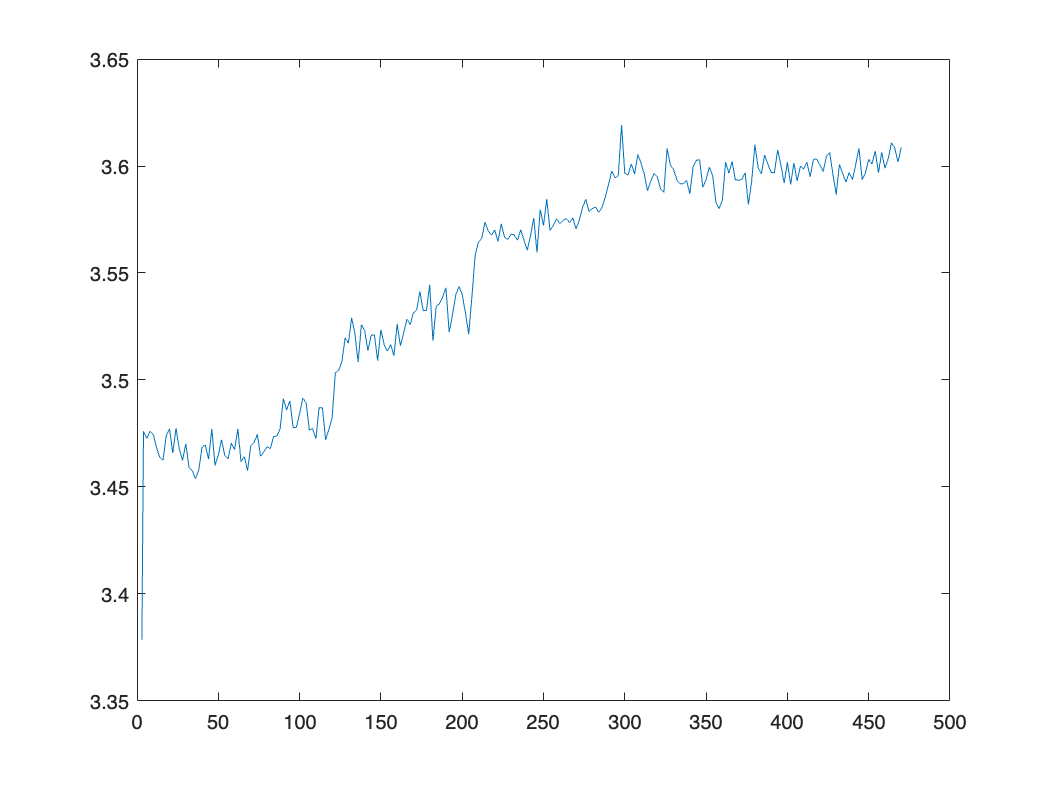

figure
plot(stateYao.CyclePositions(:,1),lft1(:,1))

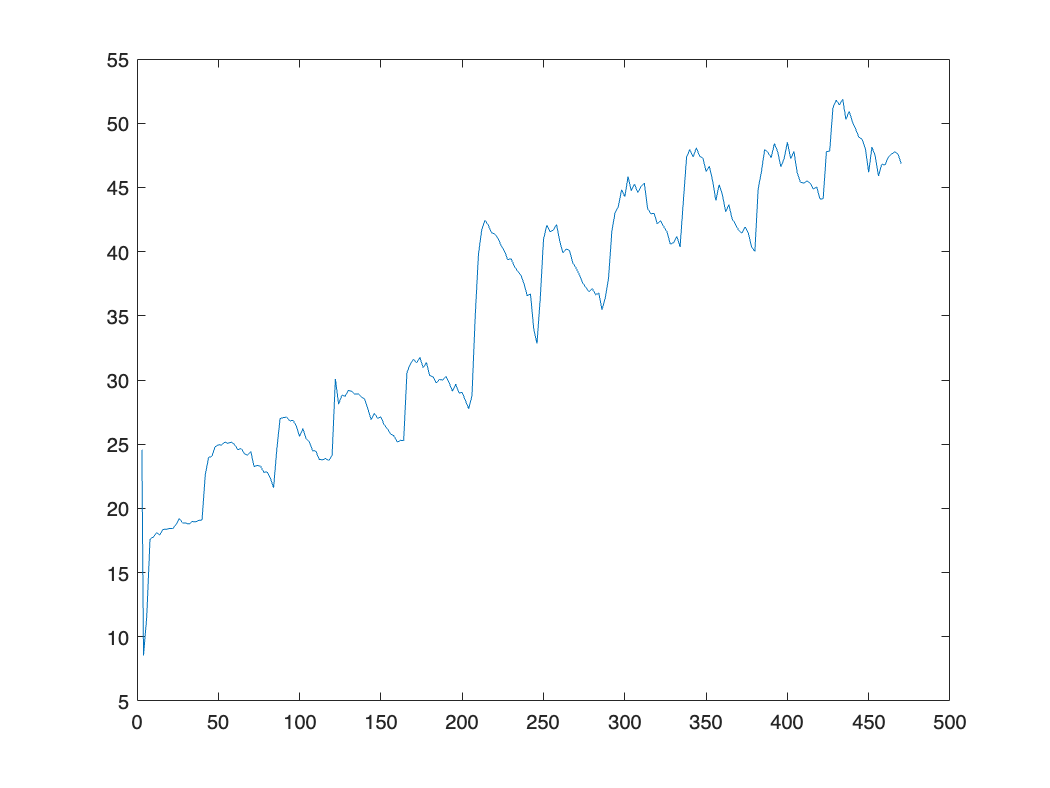


figure
plot(stateYao.CyclePositions(:,1),intensity1(:,1))